%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% This script provides an interactive demo of the clustering algorithm
% using a trainable path classifer.
% In this examples NUM_PATHS good and bad paths of length W are provided by
% the user using a graphical interface to draw paths on 2d data.
% Then, a SVM classifier is trained and integrated into the minimax
% path-cost function. Requires the Matlab Bioinformatics Toolbox
% Author: Pizzagalli D.U.
% Date: 2019-01-30
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

close all;
clear all;
clc;

## SETTINGS

PATH_DATASETS = '..\dataset\'; % Path to datasets
FN           = '99_synthetic_dendrites.txt'; % Dataset name.
DP_METHOD    = 'manual'; % Method to select density peaks: 'manual', 'fixed', 'topmost', 'otsu_topmost'
DP_MIN_RHO   = 2;        % Used with DP_METHOD = 'fixed'
DP_MIN_DELTA = 10;       % Used with DP_METHOD = 'fixed'
TH_PRUNING   = 200;      % Prunes edges whose cost is higher. 0 no pruning.
W = 5;                   % Length of path fragment for training
NUM_PATHS = 4;           % Number of training path in each class.

## DEPENDENCIES

addpath '.\utils';  %Utilities
addpath '.\libs\colorbrewer\';  %Visually different colors
addpath '.\libs\dpclustering\'; %CDP implementation
% Requires Matlab Bioinformatics Toolbox
%Licenses to 3rd parties code is added in LICENSE.txt in each folder.

## INITIALIZATION

points = dlmread([PATH_DATASETS,FN], '\t', 5, 1);
ptsC_ref = dlmread([PATH_DATASETS,FN(1:end-3),'gs.txt'], '\t', 0, 1);
points_idx = randperm(size(points,1));
points = points(points_idx, :);
ptsC_ref = ptsC_ref(points_idx, :);

points_idx

points_idx =     28    27    29    16    13    24    32    12    34     6     5    20     3    31    18    22    35    30     4    14    11    10     9    23     7     2    17    15     1     8    33    26    25    21    19


## Uncomment to normalize variables

   for dd = 1:size(points, 2)
       points(:,dd) = points(:,dd) - min(points(:,dd));
       if(max(abs(points(:,dd))) > 0)
           points(:,dd) = points(:,dd) ./ max(abs(points(:,dd)));
       end
   end

## GENERATE PATHS FOR TRAINING

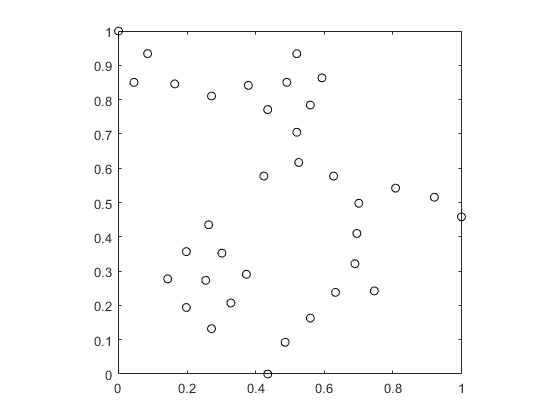

num_clusters = numel(unique(ptsC_ref));
num_points = size(points, 1);
paths_good = zeros(NUM_PATHS, W);
paths_bad = zeros(NUM_PATHS, W);

G = pdist2(points, points); %A graph (can be avoided for optimization).

figure;
plot(points(:,1), points(:,2), 'o', 'Color', [0,0,0]);
axis equal; axis square;
hold on;

## Get Good paths

for nn = 1:NUM_PATHS
    title(['Give an example (',num2str(nn),'/',num2str(NUM_PATHS),') of GOOD path - click to connect points']);
    order = zeros(num_points, 1);
    idx_old = 0;
    for ww = 1:W
        [x1,y1] = ginput(1);
        [~, idx] = min(pdist2(points(:,1:2), [x1, y1]));
        points(idx, 1)
        switch ww
            case 1
                plot(points(idx, 1), points(idx, 2), 'o', 'MarkerFaceColor', 'g');
            case W
                plot(points(idx, 1), points(idx, 2), 'o', 'MarkerFaceColor', 'r');
            otherwise
                plot(points(idx, 1), points(idx, 2), 'o', 'MarkerFaceColor', 'b');
        end
        hold on;
        paths_good(nn,ww) = idx;
        if(idx_old > 0)
            line([points(idx_old, 1); points(idx, 1)], [points(idx_old, 2); points(idx, 2)], 'Color', [0.2 0.8 0.2]);
        end
        idx_old = idx;
    end
end

% Bad paths cntaining one swap (from one cluster to another) error.
for nn = 1:NUM_PATHS
    title(['Give an example (',num2str(nn),'/',num2str(NUM_PATHS),') of BAD path - click to connect points']);
    order = zeros(num_points, 1);
    idx_old = 0;
    for ww = 1:W
        [x1,y1] = ginput(1);
        [~, idx] = min(pdist2(points(:,1:2), [x1, y1]));
        points(idx, 1)
        switch ww
            case 1
                plot(points(idx, 1), points(idx, 2), 'o', 'MarkerFaceColor', 'g');
            case W
                plot(points(idx, 1), points(idx, 2), 'o', 'MarkerFaceColor', 'r');
            otherwise
                plot(points(idx, 1), points(idx, 2), 'o', 'MarkerFaceColor', 'b');
        end
        hold on;
        paths_bad(nn,ww) = idx;
        if(idx_old > 0)
            line([points(idx_old, 1); points(idx, 1)], [points(idx_old, 2); points(idx, 2)], 'Color', [0.8 0.2 0.2]);
        end
        idx_old = idx;
    end
end

## VISUAIZATION (I) - TRAINING PATHS

figure;
subplot(121);
colors = lines(NUM_PATHS);
plot(points(:,1), points(:,2), 'o' );%, 'MarkerFaceColor', 'b'
for ii = 1:NUM_PATHS
    hold on;
    plot(points(paths_good(ii,:),1), points(paths_good(ii,:),2), '-', 'LineWidth', 2, 'Color', colors(ii,:));
end
axis equal; axis square;
title('correct paths');

subplot(122);
colors = lines(NUM_PATHS);
plot(points(:,1), points(:,2), 'o');%, 'MarkerFaceColor', 'b');
for ii = 1:NUM_PATHS
    hold on;
    plot(points(paths_bad(ii,:),1), points(paths_bad(ii,:),2), '-', 'LineWidth', 2, 'Color', colors(ii,:));
end
axis equal; axis square;
title('wrong paths');

## PATH DESCRIPTOR USING DENSITY PROFILE

percNeigh = 0.02;
kernel = 'Gauss';
[dc, rho] = paraSet(G, percNeigh, kernel); % From CDP
paths_good_features = rho(paths_good);
paths_bad_features = rho(paths_bad);

## TRAINING

X = [paths_good_features; paths_bad_features];
y = [zeros(size(paths_good_features,1),1); ones(size(paths_bad_features,1),1)];

SVMModel = fitcsvm(X,y,'Standardize',true,'KernelFunction','RBF',...
    'KernelScale','auto');
CVSVMModel = crossval(SVMModel);
classLoss = kfoldLoss(CVSVMModel); %Generalization rate

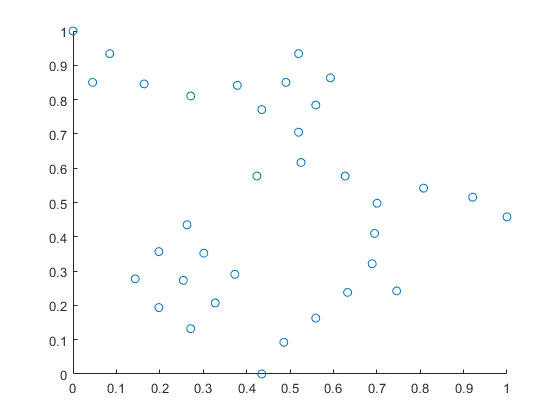

figure;
scatter(points(:,1), points(:,2));

## CDP

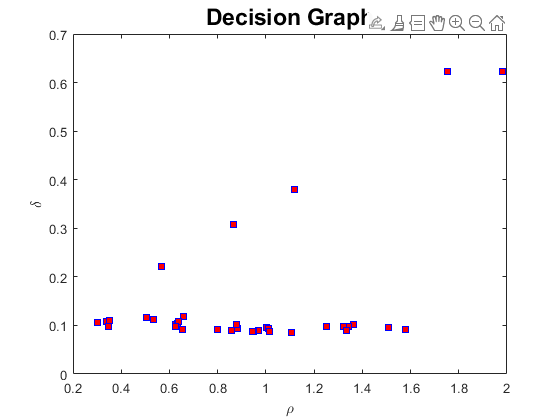

Manually select a proper rectangle to determine all the cluster centres (use Decision Graph)!
The only points of relatively high *rho* and high  *delta* are the cluster centers!


figure;
[centers_DP, ptsC_DP] = dpeuclidean(points, DP_MIN_RHO, DP_MIN_DELTA, DP_METHOD);

points(centers_DP, :)

ans =     0.2542    0.2731
    0.4907    0.8502


## Proposed algorithm with minimax

[centers_DI, ptsC_DI, path_DI] = dpshortest_minimax(points, centers_DP, TH_PRUNING);

## Proposed algorithm with path classifier

axis equal; axis square;
hold on;
[centers_DI_SVM, ptsC_DI_SVM, path_DI_SVM] = dpshortest_svm(points, centers_DP, TH_PRUNING, rho, SVMModel, W);

## Evaluation

[TP_DP,FP_DP,TN_DP,FN_DP,precision_DP,recall_DP,F1_DP,J_DP] = evaluateClusteringResults(ptsC_DP, ptsC_ref);
[TP_DI,FP_DI,TN_DI,FN_DI,precision_DI,recall_DI,F1_DI,J_DI] = evaluateClusteringResults(ptsC_DI, ptsC_ref);
[TP_DI_SVM,FP_DI_SVM,TN_DI_SVM,FN_DI_SVM,precision_DI_SVM,recall_DI_SVM,F1_DI_SVM,J_DI_SVM] = evaluateClusteringResults(ptsC_DI_SVM, ptsC_ref);

disp(['F1 (ClusterDP) on ', FN, ' = ', num2str(F1_DP)]);
disp(['F1 (ClusterDP with Shortest Path) on ', FN, ' = ', num2str(F1_DI)]);
disp(['F1 (ClusterDP with Shortest Path + SVM) on ', FN, ' = ', num2str(F1_DI_SVM)]);

## VISUALIZATION

figure;
subplot(141);
fn_str = strrep(FN, '_', '\_');
plot_clustered_points(points, ptsC_ref, false);
axis equal; axis square;
title('Ground truth');

subplot(142);
plot_clustered_points(points, ptsC_DP, false);
hold on;
plot(points(centers_DP, 1), points(centers_DP, 2), '*', 'MarkerEdgeColor', [0,0,0], 'MarkerSize', 4);
title(['CDP F1=',num2str(F1_DP, '%.2f'),' J=',num2str(J_DP, '%.2f')]);
axis equal; axis square;

subplot(143);
plot_clustered_points(points, ptsC_DI, false);
hold on;
plot(points(centers_DI, 1), points(centers_DI, 2), '*', 'MarkerEdgeColor', [0,0,0],  'MarkerSize', 4);
title(['Ours (generic) F1=',num2str(F1_DI, '%.2f'),' J=',num2str(J_DI, '%.2f')]);
axis equal; axis square;

subplot(144);
plot_clustered_points(points, ptsC_DI_SVM, false);
hold on;
plot(points(centers_DI_SVM, 1), points(centers_DI_SVM, 2), '*', 'MarkerEdgeColor', [0,0,0],  'MarkerSize', 4);
title(['Ours (trained) F1=',num2str(F1_DI_SVM, '%.2f'),' J=',num2str(J_DI_SVM, '%.2f')]);
axis equal; axis square;